# MPC HW7

%   Author: Lucky Yerimah
%   Date: March 26 2020

%   Three tank plant data   

A = [-1, 0, 0; 1, -1, 0; 0, 1, -1];
B = [1;0;0];
C = [0,0,1];
D = 0;
sys = ss(A,B,C,D); % converting matrices to state space 
Gz = c2d(sys,0.5); % Discrete-time transfer function
x0 = [0;0;0]; % initial conditions for the states
[phi,gamma,Cz,Dz] = ssdata(Gz);
tbeng = 0;
deltaT = 0.5;

Problem one

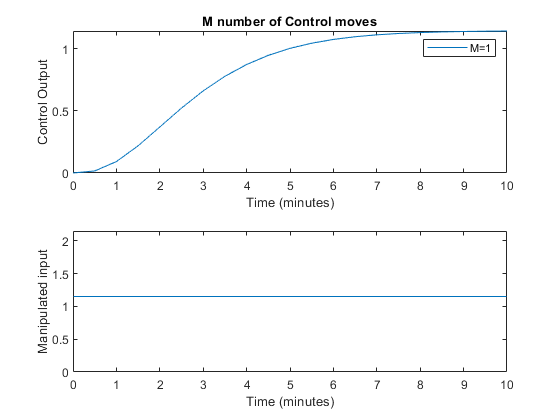


% 
P = 20; 
sumf = 0;
r = ones(P,1);
uk_1 = 0; % u(k-1)
x0 = [0;0;0]; % initial conditions for the states
for j=1:P
    sumf = sumf + Cz*phi^(j-1)*gamma;
    Sf(j,1) = sumf;
    Cphi(j,:) = Cz*phi^(j); 
end

A_M1 = Sf;
E = r - Sf*x0' - Cphi*uk_1; % free response error vector
delta_u1 = pinv(A_M1)*E; % solution using the pinv function
M_moves1(1,1) = delta_u1(1);
M_moves1(2:P,1) = zeros(P-1,1);
u_M_Moves1 = cumsum(M_moves1); % manipulated inputs

tend = P/2;
time = tbeng:deltaT:tend;
for k = 1:length(time)-1
    [~,xnew] = ode45(@(t,x) plantmodel(t,x,u_M_Moves1(k,1)),[time(k) time(k+1)], x0); % ODE45 function
ym1(k+1) = xnew(end,end); % output as last value of xnew
x0= xnew(end,:)'; % assigning states variables as input for next iteration
end
u_M_Moves1(k+1) = u_M_Moves1(k);

figure(4)
subplot(2,1,1)
plot(time,ym1)
xlabel('Time (minutes)')
ylabel('Control Output')
legend('M=1')
title("M number of Control moves")

subplot(2,1,2)
stairs(time,u_M_Moves1)
xlabel('Time (minutes)')
ylabel('Manipulated input')

Problem two

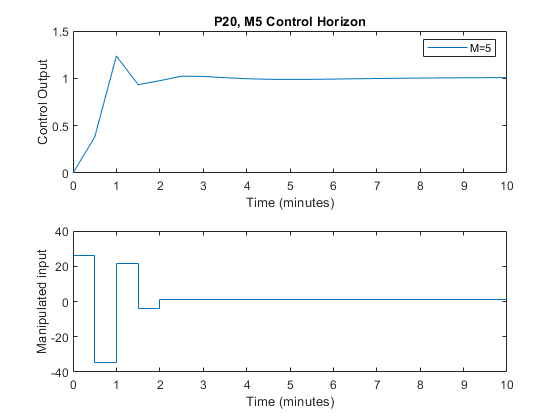


M=5; % Control horizon
sf = zeros(P,M); % initial zeros for DMC matrix 
x0 = [0;0;0]; % initial conditions for the states
for j=1:M
    zero_DMC = zeros(j-1,1);
    sf(:,j) = cat(1,zero_DMC,Sf(1:end+1-j,1)); %DMC 
end

DMC_M5 = sf;
delta_u5 = pinv(DMC_M5)*E;
M_moves5(1:5,1) = delta_u5(:,1);
M_moves5(6:P,1) = zeros(P-5,1);
u_M_Moves5 = cumsum(M_moves5); % Control moves

tend = P/2;
time = tbeng:deltaT:tend;
for k = 1:length(time)-1
    [~,xnew] = ode45(@(t,x) plantmodel(t,x,u_M_Moves5(k,1)),[time(k) time(k+1)], x0); % ODE45 function
ym5(k+1) = xnew(end,end); % output as last value of xnew
x0= xnew(end,:)'; % assigning states variables as input for next iteration
end
u_M_Moves5(k+1) = u_M_Moves5(k);

figure(4)
subplot(2,1,1)
plot(time,ym5)
xlabel('Time (minutes)')
ylabel('Control Output')
legend('M=5')
title("P20, M5 Control Horizon")

subplot(2,1,2)
stairs(time,u_M_Moves5)
xlabel('Time (minutes)')
ylabel('Manipulated input')

## Continuous Plant

function xdot = plantmodel(t,x,u)
% State space equations 
xdot(1) = -x(1) + u;
xdot(2) = x(1) - x(2);
xdot(3) = x(2) - x(3);

xdot = xdot'; % converting the ODEs to column vector
end